# Mapping NYC Yellow Cab pickups

Copyright 2016 The MathWorks, Inc.

In this demo, we're going to use publicly available [NYC yellow cab data sets](http://www.nyc.gov/html/tlc/html/about/trip_record_data.shtml) and mimic one of the [plots in Loren's blog](http://blogs.mathworks.com/loren/2016/01/20/mapping-uber-pickups-in-new-york-city/) which shows a map of Uber pick-ups in New York. We'll produce a heat-map of yellow cab pick-ups over the same geographical area.

**[Note: You only need to download 1 .csv file from any year to get things going.]**

## `(Change if you like)` Define data access and processing parameters

Decide here whether or not you want to test the data on a smaller set of data, **and/or** whether or not you want to process your data on a Spark cluster.

You can also decide whether or not you want to create a .gif of hourly pickups based on all the data.

useSparkCluster = 0; % 1 = true, 0 = false
useAllData = 0;

% Creating the .gif takes quite a bit of time. I recommend setting this to '1' only if
% you can utilize a compute cluster, or
% you are just running this on one month's worth of data, or
% you have hours to kill =P
createGif = 0;
gifFilename = 'NYC2015HourlyPickups.gif'; % you need the '.gif'

## `(INPUT NEEDED)` Tell MATLAB where your files are stored (.csv files + wms.mat + load_settings.m) and Hadoop/Spark path

The following sub-script assumes that all the files you downloaded are stored in the same place. Please be sure to specify the correct paths.

allMyFilesAreStoredHere = 'path/to/your/data';

% You do not need to set these if you're just running on your local machine
hadoop_path = 'path/to/your/Hadoop';
spark_path = 'path/to/your/Spark';

addpath(allMyFilesAreStoredHere)


## Let's get it started!

if useSparkCluster
    numWorkers = 16; 
    setenv('HADOOP_HOME', hadoop_path);
    setenv('SPARK_HOME', spark_path);
    cluster = parallel.cluster.Hadoop;
    cluster.SparkProperties('spark.executor.instances') = num2str(numWorkers);
    mr = mapreducer(cluster);
end

% use all csv files found in the folder
filePath = [allMyFilesAreStoredHere '*.csv'];

% You don't have to specify data formats for the datastore, but it does helps MATLAB.
ds = datastore(filePath,...
        'TextscanFormats', ...
            {'%C', '%{yyyy-MM-dd HH:mm:ss}D', '%{yyyy-MM-dd HH:mm:ss}D', '%u8', '%f', ...
            '%f', '%f', '%C', '%C', '%f', '%f', '%C', '%f', '%f', '%f', '%f', '%f', '%f', '%f'}, ...
        'SelectedVariableNames', ...
            {'tpep_pickup_datetime', 'pickup_latitude', 'pickup_longitude'});

ds =   TabularTextDatastore with properties:

                      Files: {
                             '\\mathworks\devel\sandbox\gha\NYC-Cab-Data\yellow_tripdata_2015-01.csv';
                             '\\mathworks\devel\sandbox\gha\NYC-Cab-Data\yellow_tripdata_2015-02.csv';
                             '\\mathworks\devel\sandbox\gha\NYC-Cab-Data\yellow_tripdata_2015-03.csv'
                              ... and 9 more
                             }
               FileEncoding: 'UTF-8'
          ReadVariableNames: true
              VariableNames: {'VendorID', 'tpep_pickup_datetime', 'tpep_dropoff_datetime' ... and 16 more}

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%*q',


months_of_data = size(ds.Files, 1); % this number changes dynamically based on how many .csv files you're using.
preview(ds)

## Examine column variables

Use this code to quickly reference the column names of your data.

% for i = 1:size(ds.VariableNames,2)
%     disp([i,ds.VariableNames(1,i)])
% end

## "Bring into" tall array, derive values, and remove outliers

Read the datastore into a tall table. tt = tall(ds); It's that simple.

% Create tall array from datastore.
tt = tall(ds); % yep. that's it.

Starting a Spark Job on the Hadoop cluster. This could take a few minutes ...done.



% This is needed to run script a 2nd time. Doesn't hurt the 1st run.
clear hour 

% Derive new values with simple syntax.
tt.HourOfPickup = hour(tt.tpep_pickup_datetime);

% For prototyping, use a subset of your data
ttSubarray = tt;
if ~useAllData
    ttSubarray = head(tt,1000);
end

## Convert data into heat map

See [Loren's blog](http://blogs.mathworks.com/loren/2016/01/20/mapping-uber-pickups-in-new-york-city) for details.

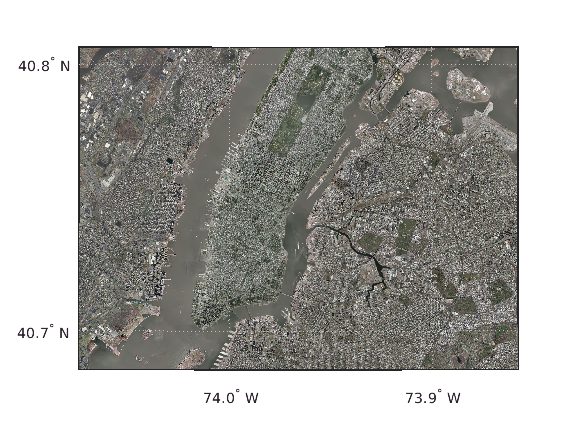

load_settings
load wms

figure                                                  % create a new figure
usamap(lim.lat, lim.lon);                               % limit to New York area
geoshow(A, R)                                           % display raster map


nbins = 250;                                            % number of bins
xbinedges = linspace(lim.lon(1),lim.lon(2),nbins);      % x-axis bin edges
ybinedges = linspace(lim.lat(1),lim.lat(2),nbins);      % y-axis bin edges
map = flipud(A);                                        % flip image


threshold = 350000 / months_of_data; 
% plot all data, unfiltered
figure
imagesc(lim.lon, lim.lat, map)                          % show raster map
hold on                                                 % don't overwrite
colormap cool                                           % set colormap
histogram2(ttSubarray.pickup_longitude, ...             % overlay histogram...
    ttSubarray.pickup_latitude, ...                     % ...in 2D style
    xbinedges, ybinedges, ...                                           
    'DisplayStyle', 'tile', ...                         
    'FaceAlpha', 0.5)
hold off                                                % restore default
caxis([0 threshold])                                    % make color axis scaling consistent
daspect(dar)                                            % adjust ratio
set(gca,'ydir','normal');                               % fix y orientation
title({'2015 NYC Yellow Taxi Pickup Locations'})        % add title
text(lmk1.lon, lmk1.lat, lmk1.str, 'Color', 'w');       % add landmarks
text(lmk2.lon, lmk2.lat, lmk2.str, 'Color', 'w', ...    % add landmarks
    'HorizontalAlignment', 'right');
colorbar                                                % add colorbar

## Create .gif of pickups per hour

     0



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.6833 min

Evaluation completed in 5.7167 min


     1



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.3 min

Evaluation completed in 5.3167 min


     2



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.25 min

Evaluation completed in 5.25 min


     3



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2333 min

Evaluation completed in 5.25 min


     4



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2 min

Evaluation completed in 5.2167 min


     5



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2167 min

Evaluation completed in 5.2167 min


     6



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.1833 min

Evaluation completed in 5.2 min


     7



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2167 min

Evaluation completed in 5.2167 min


     8



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2167 min

Evaluation completed in 5.2333 min


     9



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2 min

Evaluation completed in 5.2 min


    10



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2 min

Evaluation completed in 5.2 min


    11



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2 min

Evaluation completed in 5.2 min


    12



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2167 min

Evaluation completed in 5.2167 min


    13



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2 min

Evaluation completed in 5.2 min


    14



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2 min

Evaluation completed in 5.2 min


    15



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.1833 min

Evaluation completed in 5.1833 min


    16



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2167 min

Evaluation completed in 5.2167 min


    17



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.1833 min

Evaluation completed in 5.1833 min


    18



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2167 min

Evaluation completed in 5.2167 min


    19



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.1833 min

Evaluation completed in 5.1833 min


    20



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.1833 min

Evaluation completed in 5.2 min


    21



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2 min

Evaluation completed in 5.2 min


    22



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.2167 min

Evaluation completed in 5.2167 min


    23



Evaluating tall expression using the Spark Cluster:

- Pass 1 of 1: Completed in 5.1833 min

Evaluation completed in 5.2 min


if createGif
    figure                                                  % create a new figure
    usamap(lim.lat, lim.lon);                               % limit to New York area
    geoshow(A, R)                                           % display raster map
    
    filterResults = 0;                                      % set to 1 for a cleaner-looking .gif
    maxThreshold = 25000 / months_of_data;
    
    first = true;                                           % flag
    timesOfDay = {'12AM','1AM','2AM','3AM',...              % labels for .gif
        '4AM','5AM','6AM','7AM','8AM',...
        '9AM','10AM','11AM','12PM',...
        '1PM','2PM','3PM','4PM','5PM',...
        '6PM','7PM','8PM','9PM','10PM','11PM'};
    
    figure('Visible', 'off')                                % make plot invisible
    for i = 0:23                                            % loop over hour
        disp(i);
        imagesc(lim.lon, lim.lat, map)                      % show raster map
        hold on                                             % don't overwrite
        colormap cool                                       % set colormap
        matchingIndices = ttSubarray.HourOfPickup == i;     % pick data by hour
        h = histogram2(...
            ttSubarray.pickup_longitude(matchingIndices), ... % overlay histogram...
            ttSubarray.pickup_latitude(matchingIndices), ...  % ...in 2D style
            xbinedges, ybinedges, 'DisplayStyle', 'tile');
        
        if filterResults                                    % makes the .gif look cleaner...
            h.BinCounts(h.BinCounts < maxThreshold/24) = 0; % ...by not plotting histogram bins...
        end                                                 % ...beneath a certain threshold
        
        hold off                                            % restore default
        xlim(lim.lon)                                       % limit x range
        ylim(lim.lat)                                       % limit y range
        daspect(dar)                                        % adjust ratio
        set(gca,'ydir','normal');                           % fix y orientation
        title('NYC Taxi Pickup Locations by Hour')          % add title
        text(cir.ctr(2), cir.ctr(1), ...                    % add timesOfDay entries in upper left corner of the map
            {timesOfDay{i+1}}, ...                                   
            'Color', 'w', 'FontSize', 20, ...               
            'FontWeight', 'bold', ...
            'HorizontalAlignment', 'center')
        text(lmk1.lon, lmk1.lat, lmk1.str, 'Color', 'w');   % add landmarks
        text(lmk2.lon, lmk2.lat, lmk2.str, 'Color', 'w', ...% add landmarks
        'HorizontalAlignment', 'right');
        caxis([0 maxThreshold])                             % make color axis scaling consistent
        colorbar                                            % add colorbar
        fname = getframe(gcf);                              % get the frame
        [x,cmap] = rgb2ind(fname.cdata, 128);               % get indexed image
        if first                                            % if first frame...
            first = false;                                  % ...update flag
            imwrite(x,cmap, gifFilename, ...                % save as GIF
                'Loopcount', Inf, ...                       % loop animation
                'DelayTime', 1);                            % 1 frame per second
        else                                                % if image exists...
            imwrite(x,cmap, gifFilename, ...                % ...append frame to the image
                'WriteMode', 'append', 'DelayTime', 1);     
        end
    end
end